% Load file names
expNum = '07292025';
scanName = 'Scan_4';
folderPath = "Users\Lab User\Desktop\experiment data";
filePath = fullfile('C:\',folderPath,expNum,strcat(scanName, '.hdf5')); 
dataFolder = 'RawData';
dataPath = strcat('/',dataFolder,'/',scanName);

% Load & crop data
data = h5read(filePath, dataPath);
data = permute(data, [2,1,3]); % (y,x,z)
fprintf("Original:(%d,%d,%d) [y,x,z]\n", size(data));

Original:(1224,1024,852) [y,x,z]



% Crop ROI
[yMin, yMax, xMin, xMax] = deal(160, 1080, 66, 956);
dataCropped = double(data(yMin:yMax, xMin:xMax, :)); %GPU
cropSz = size(dataCropped); [yDim, xDim, zDim] = size(dataCropped);
fprintf("Cropped:(%d,%d,%d)\n", cropSz);

Cropped:(921,891,852)


% Find extremes & Median filter salt
highPct = 99; medPct = 95;
threshHigh = prctile(dataCropped(:), highPct);
filteredData = medfilt3(dataCropped, [3 3 3]);
dataCropped(dataCropped > threshHigh) = filteredData(dataCropped > threshHigh);
threshHigh = prctile(dataCropped(:), highPct);
meanMed = mean(prctile(dataCropped(:), medPct));
dataCropped(dataCropped > threshHigh) = meanMed;
fprintf("Applied median filter\n")

Applied median filter



% Normalize
dataNorm = mat2gray(dataCropped);
dataNorm = max(min(dataNorm,1),0);

% Column-wise normalization
meanPerCol = squeeze(mean(mean(dataNorm,2),3));
scaleFactors = meanPerCol(floor(yDim/2)) ./ meanPerCol;
dataColNorm = dataNorm .* reshape(scaleFactors, [yDim,1,1]);
dataColNorm = max(min(dataColNorm, 1), 0);
dataReNorm = mat2gray(dataColNorm);

% Sharpen image
strength = 0.2;
blurred = imgaussfilt3(dataColNorm, 3);
dataSharp = dataReNorm - strength*(dataReNorm - blurred);
dataSharp = max(min(dataSharp, 1), 0);

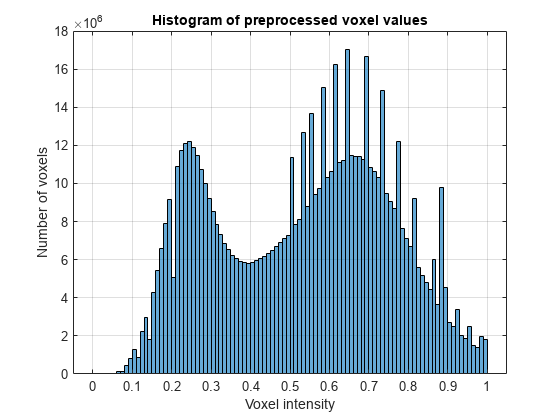


% Show steps
figure;
histogram(dataNorm, 100);          % 100 bins
xlabel('Voxel intensity');
ylabel('Number of voxels');
title('Histogram of preprocessed voxel values');
grid on;

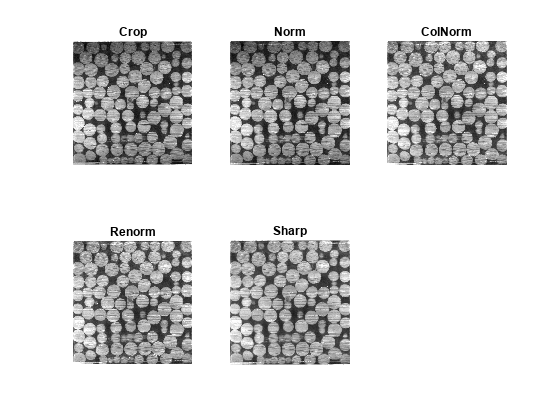

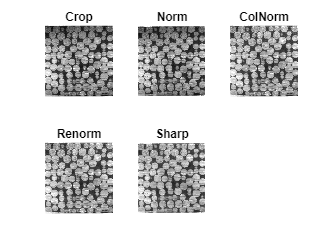

drawnow;

figure; 
subplot(2,3,1); imshow(dataCropped(:,:,floor(zDim/2)), []); title('Crop');
subplot(2,3,2); imshow(dataNorm(:,:,floor(zDim/2)), []); title('Norm');
subplot(2,3,3); imshow(dataColNorm(:,:,floor(zDim/2))); title('ColNorm');
subplot(2,3,4); imshow(dataReNorm(:,:,floor(zDim/2))); title('Renorm');
subplot(2,3,5); imshow(dataSharp(:,:,floor(zDim/2))); title('Sharp')

drawnow;

% Downsample for speed
scaleFactor = 0.5;

dataRescale = imresize3(dataSharp, scaleFactor, 'linear');
[Ny, Nx, Nz] = size(dataRescale);
fprintf("Rescaled:(%d,%d,%d)\n", Ny, Nx, Nz);

Rescaled:(461,446,426)



% Particle tracking parameters
D = 100 * scaleFactor;         % initial particle diameter
w = 2.5 * scaleFactor;        % initial width parameter
Cutoff = 5;     % minimum peak intensity
MinSep = 75 * scaleFactor;     % minimum separation between peaks
eps = 1e-12;

% Setup ideal particle grid
ss = 2*fix(D/2 + 4*w/2) - 1;
os = (ss-1)/2;
[xx, yy, zz] = ndgrid(-os:os, -os:os, -os:os);
r = sqrt(xx.^2 + yy.^2 + zz.^2);

% Find pixel-accurate centers
ipi = ipf3D(r, D, w);
[chi3D, Wip2] = chiimg3D_FFT(dataRescale, ipi);
[Np, px, py, pz] = findpeaks3D(1./(chi3D + eps), ones(size(chi3D)), Cutoff, MinSep);
fprintf("Found %d initial peaks\n", Np);

Found 680 initial peaks


szIpi = size(ipi);

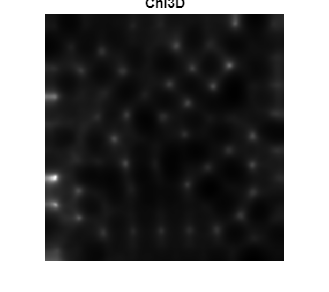

figure;
imshow(1./(chi3D(:,:,floor(Nz/2))+eps), []); title("Chi3D")
hold on;

plot(py,px);

Error using plot
Data must be a single input of y-values or one or more pairs of x- and y-values.

hold off;
drawnow;

fprintf("      Temp | Data\n");
fprintf("Min: (%.2f, %.2f)\n",min(ipi(:)),min(dataRescale(:)));
fprintf("Max: (%.2f, %.2f)\n",max(ipi(:)),max(dataRescale(:)));
fprintf("Mean:(%.2f, %.2f)\n",mean(ipi(:)),mean(dataRescale(:)));

% Sub-voxel chi-squared minimization
[cxyz, over] = pgrid3D(px, py, pz, Nx, Ny, Nz, Np, os, 0); % full-size vector grids
r_full = sqrt(cxyz.x.^2 + cxyz.y.^2 + cxyz.z.^2);
r_full = permute(r_full, [2,1,3]);   % Now size = [Ny, Nx, Nz], matches dataRescale

ci = ipf3D(r_full, D, w);
di = ci - dataRescale;
chi2 = sum(di(:).^2);

fprintf('Initial Error=%.2e\n', chi2);
fprintf("      Ci | Data\n");
fprintf("Min: (%.2f,%.2f)\n", min(ci(:)), min(dataRescale(:)));
fprintf("Max: (%.2f,%.2f)\n",max(ci(:)), max(dataRescale(:)));
fprintf("Overall Delta: %.2f\n", norm(ci(:) - dataRescale(:)));

% Optimize particle positions
nr = 0; delchi2 = 1e99;
mindelchi2 = 1; maxnr = 5;

while abs(delchi2) > mindelchi2 && nr < maxnr
    [dpx, dpy, dpz] = cidp23D(cxyz, over, di, Np, D, w);
    px = px + dpx; py = py + dpy; pz = pz + dpz;
    
    [cxyz, over] = pgrid3D(px, py, pz, Nx, Ny, Nz, Np, os, 0);
    r_full = sqrt(cxyz.x.^2 + cxyz.y.^2 + cxyz.z.^2);
    r_full = permute(r_full, [2,1,3]);  % critical: match dataRescale
    
    ci = ipf3D(r_full, D, w);
    di = ci - dataRescale;
    
    delchi2 = chi2 - sum(di(:).^2);
    chi2 = chi2 - delchi2;
    
    fprintf('.');
    nr = nr + 1;
end
fprintf('\nFinal Chi-Squared=%.2e\n', chi2);

% Max projection
figure;
imagesc(max(di.^2,[],3)); axis image; colormap(gray);
title(sprintf('Residual chi-squared (max projection), Chi^2=%6.2f', chi2));

% Scatter plot of particle centers
figure;
scatter3(px, py, pz, 50, 'r', 'filled');
axis([1 Nx 1 Ny 1 Nz]); axis equal; grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Detected particle centers');

% Rescale data
peaks = [py(:), px(:), pz(:)] ./ scaleFactor;
dataFinal = imresize3(dataRescale, 1/scaleFactor, 'linear');

fprintf("(%.2f,%.2f,%.2f)\n", size(dataFinal));
fprintf("(%.2f,%.2f,%.2f)\n", dataFinal(1:10,1:10,1:10));

fprintf("Type: %s\n", underlyingType(peaks));
fprintf("Type: %s\n", underlyingType(dataFinal));

fprintf("Stuff: %f\n", dataFinal(1:10,40,1));
fprintf("Stuff: %d\n", length(dataFinal(:)));



% Save prediction data
peakLoc = "./DataOutput/Peaks_Scan_4.mat";
volLoc = "./DataOutput/Volume_Scan_4.h5";


if ~exist('DataOutput', 'Dir')
    mkdir('DataOutput');
end
if isfile(peakLoc) && isfile(volLoc)
    delete(peakLoc); 
    delete(volLoc);
end

save(peakLoc, 'peaks');
h5create(volLoc, '/dataFinal', size(dataFinal))
h5write(volLoc, '/dataFinal', dataFinal);

fprintf("Saved predictions\n")

whos dataFinal

whos('-file','./DataOutput/Peaks_Scan_4.mat')
whos('-file','./DataOutput/Volume_Scan_4.mat')